# Transformacja odwrotna – perfekcyjna rekonstrukcja

to get results run exc01

clear all

S = A.';

if eye(N) == S*A
    disp("SA==I")
else
    disp("SA!=I")
end

SA!=I



% random values matrix 20x20 
rand_matrix = zeros(N,N,100);
X_matrix = zeros(N,N,100);
xs_matrix = zeros(N,N,100);
similarity_matrix = zeros(1,100);
for i=1:100
    rand_matrix(:,:,i) = randn(N);
    X_matrix(:,:,i) = A*rand_matrix(:,:,i);
    xs_matrix(:,:,i) = S*X_matrix(:,:,i);
    similarity_matrix(i) = norm(rand_matrix(:,:,i)-xs_matrix(:,:,i));
end

similarity_matrix

similarity_matrix = 	1.0e+-13 *

    0.1773    0.1637    0.1712    0.2074    0.1573    0.1818    0.1563    0.1790    0.1772    0.2139    0.1604    0.1657    0.1668    0.1921    0.1829    0.2137    0.1751    0.1772    0.1899    0.1629    0.1841    0.2060    0.1548    0.1837    0.1794    0.1894    0.1234    0.2300    0.2230    0.1688    0.1827    0.2025    0.2000    0.1783    0.1760    0.1696    0.2037    0.1699    0.1958    0.1768    0.1874    0.1562    0.1584    0.1701    0.1959    0.1916    0.1890    0.1592    0.1995    0.2311


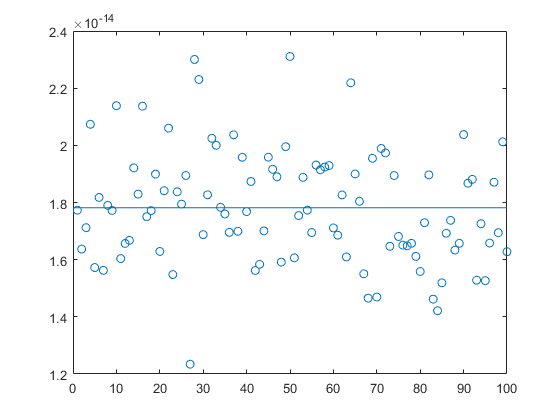


clf
figure
plot(similarity_matrix, 'o')
hold on 
hline = refline([0 mean(similarity_matrix)]);